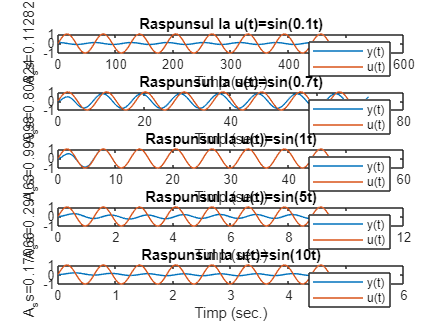

clear variables

R=1; C=1; L=1;
w=[0.1,0.7,1,5,10];%pulsatii din zona benzii de trecere
ftb=tf([R/L 0],[1 R/L 1/L/C]);% functia de transfer pt. FTB
for i=1:length(w)
    subplot(length(w),1,i);
    T=2*pi/w(i);%perioada semnalului de intrare
    t=0:T/100:8*T;%timp de simulare
    y=lsim(ftb,sin(w(i)*t),t);%raspunsul la semnal sinus
    plot(t,y,t,sin(w(i)*t));legend('y(t)','u(t)')
    title(['Raspunsul la u(t)=sin(',num2str(w(i)),'t)']);
    ylabel(['A_y_ss=',num2str((max(y)))]);xlabel('Timp (sec.)')
end


%5.1
%par. drepte
%pas 1
%obiect tf
%raspunsul LTI
%da
%da